# Análise de sistema em tempo discreto

clear all;
clc;
close all;


## Definindo a função de tranferência


$$G(z)=\frac{z}{z-e^{-aTs}$$


a = 1;                  % polo
T = 4/a;                % tempo para atingir a convergência estipulada (2%)
Ts = 0.05;               % N pontos até o sinal convergir - N = 40   

Nz = [1 0];             % Numerador da função
Dz = [1 -exp(-a*Ts)];   % Denominador da função
    
N = 1;                  % tempo contínuo         
D =[1 a];               % tempo contínuo
G =tf(N,D);             % Função em tempo continuo 
Gz = tf(Nz,Dz,Ts)       % Função de transferência

Gz =
 
      z
  ----------
  z - 0.9512
 
Sample time: 0.05 seconds
Discrete-time transfer function.



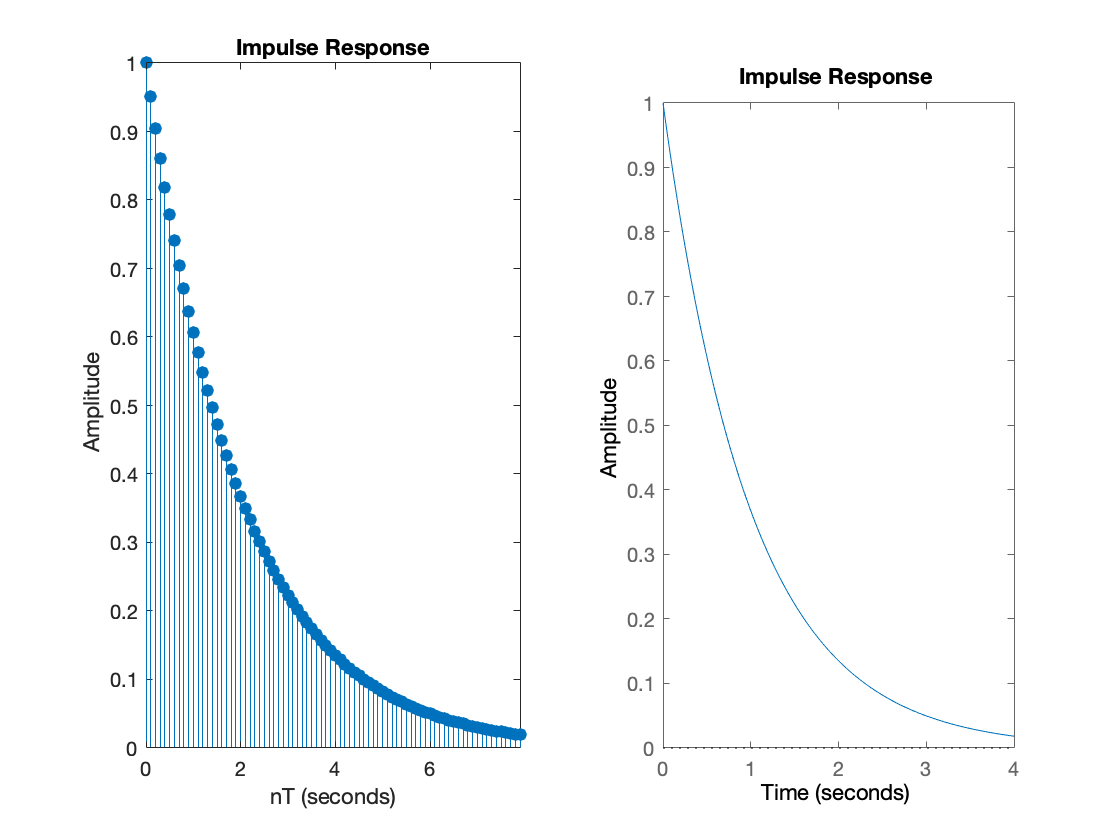


figure()

subplot(1,2,1)
impz(Nz,Dz,T/Ts,10)

subplot(1,2,2)
impulse(N,D,4)


k = [0:1:39]

k =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39


y = [1 0.9048*(ones(1,39))].^k

y =     1.0000    0.9048    0.8187    0.7407    0.6702    0.6064    0.5487    0.4964    0.4492    0.4064    0.3677    0.3327    0.3010    0.2724    0.2465    0.2230    0.2018    0.1826    0.1652    0.1495    0.1352    0.1224    0.1107    0.1002    0.0906    0.0820    0.0742    0.0671    0.0607    0.0550    0.0497    0.0450    0.0407    0.0368    0.0333    0.0302    0.0273    0.0247    0.0223    0.0202


    
figure()
stem(k*Ts,y,"LineWidth",2);
hold;

Current plot held


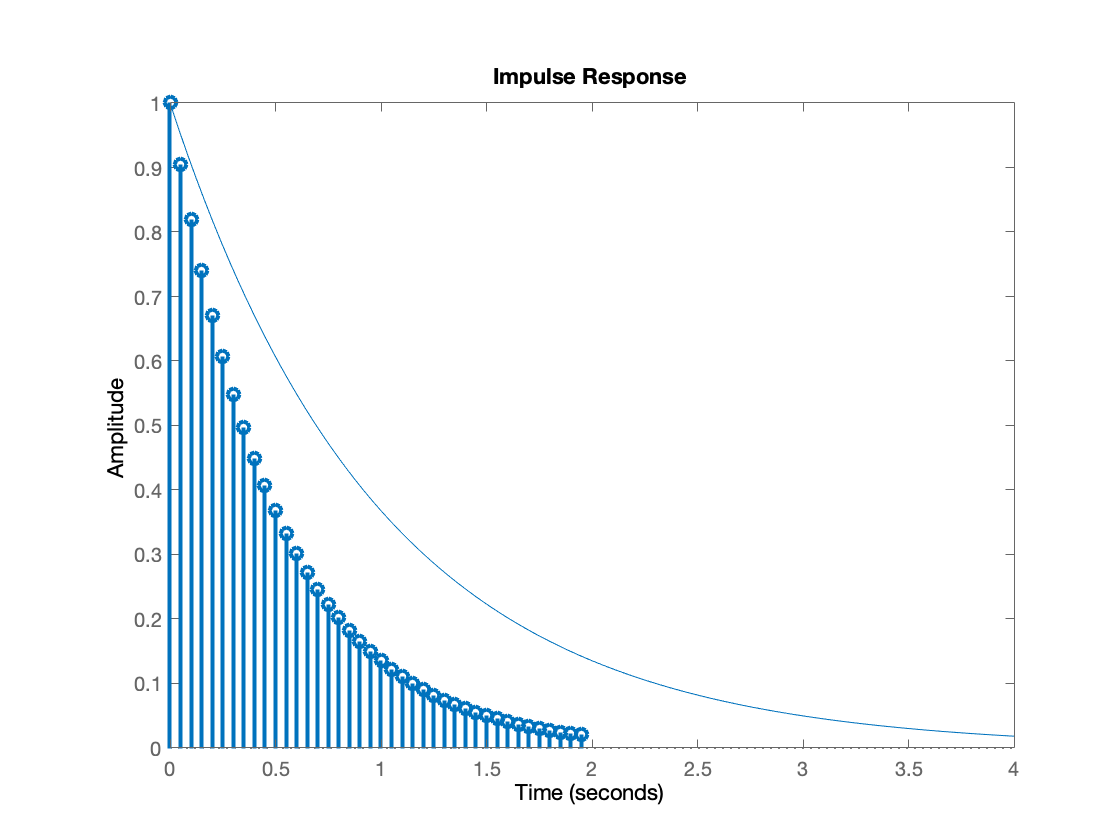

impulse(N,D,4)

## Análise de um sistema de segunda ordem


$$G(z)=\frac{z}{z-e^{-p_1Ts}}+\frac{z}{z-e^{-p_2
Ts}$$


p1 = -j*2*pi;
p2 = j*2*pi;

Nz1 = [1 0];
Dz1 = [1 -exp(-p1*Ts)];

Gz1 = tf(Nz1,Dz1,Ts)

Gz1 =
 
           z
  -------------------
  z - (0.9511+0.309i)
 
Sample time: 0.05 seconds
Discrete-time transfer function.




Nz2 = [1 0];
Dz2 = [1 -exp(-p2*Ts)];

Gz2 = tf(Nz2,Dz2,Ts)

Gz2 =
 
           z
  -------------------
  z - (0.9511-0.309i)
 
Sample time: 0.05 seconds
Discrete-time transfer function.



Gzeq = Gz1 + Gz2

Gzeq =
 
   2 z^2 - 1.902 z
  -----------------
  z^2 - 1.902 z + 1
 
Sample time: 0.05 seconds
Discrete-time transfer function.



Deq = cell2mat(Gzeq.Denominator)

Deq =     1.0000   -1.9021    1.0000


Neq = cell2mat(Gzeq.Numerator)

Neq =     2.0000   -1.9021         0


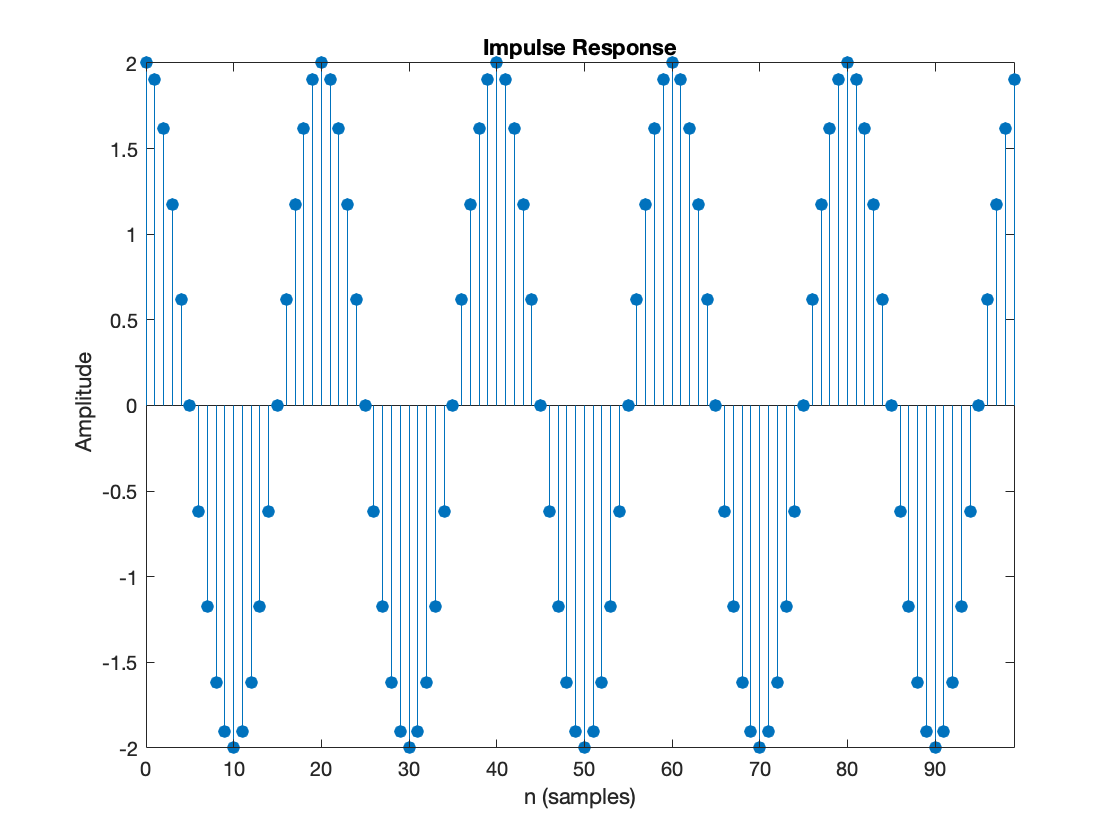

figure()

impz(Neq,Deq)

## Mapeamento s em z


z1 = exp(-j*0.2*pi)  % euler módulo - sqrt(cosˆ2 _+ senˆ2 ) = 1 

z1 = 0.8090 - 0.5878i

z2 = exp(j*0.2*pi)

z2 = 0.8090 + 0.5878i

abs(z1)

ans = 1

abs(z2)

ans = 1

roots(Deq)

ans =    0.9511 + 0.3090i
   0.9511 - 0.3090i


## Analisando como software

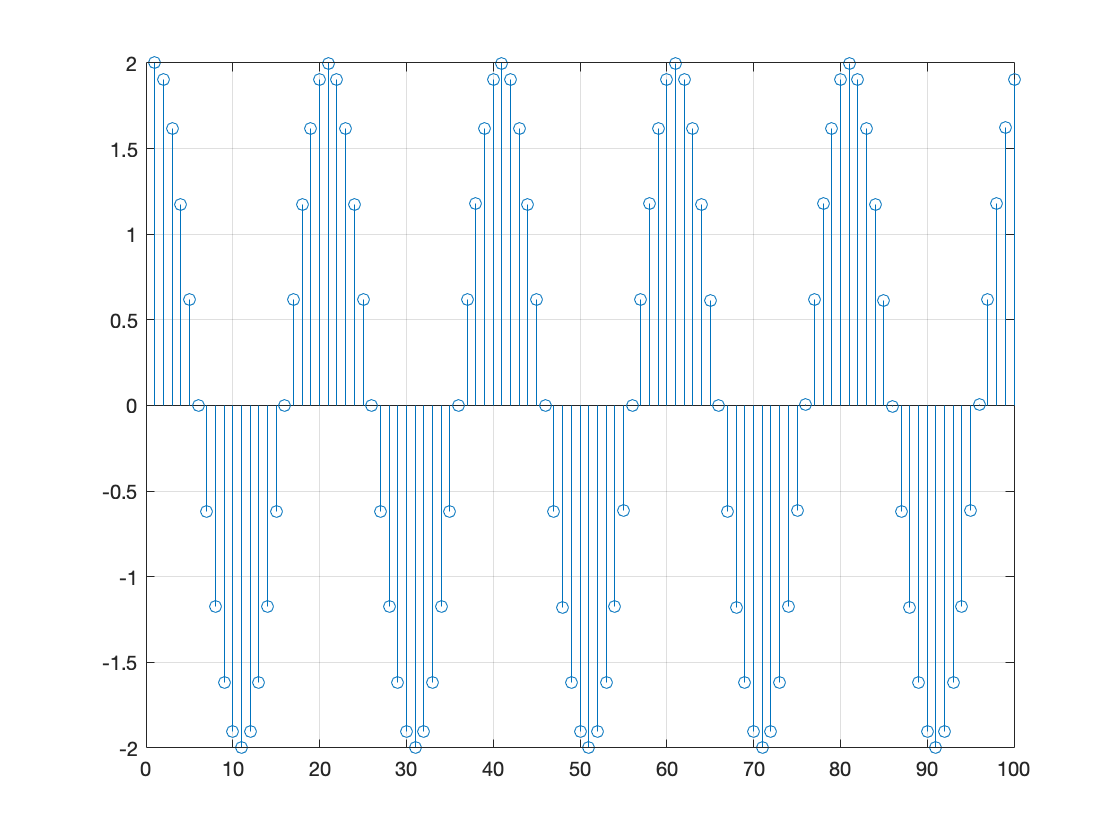


x = [1 zeros(1,99)];
xa = 0;
ya = 0;
ya2 = 0;

for k =1:length(x)
    
  [xa,y(k),ya,ya2] = senoide(x(k),xa,ya,ya2); 
  
end

figure()

stem(y); 
grid;